%wind导入历史行情序列
w = windmatlab;
w.isconnected

ans = 1

begintime='20030725';     %股票上市日
endtime='20201014';       %可转债上市前一日
[w_wsd_data,w_wsd_codes,w_wsd_fields,w_wsd_times,w_wsd_errorid] = w.wsd('600029.SH','close',begintime,endtime,'Priceadj=B','tradingcalendar=SSE','Days=Trading')  %获取收盘价（后复权）

w_wsd_data =     3.8800
    3.9200
    3.9200
    4.0800
    4.0500
    4.0200
    4.0300
    4.0100
    3.9800
    4.0000


w_wsd_codes = 1×1 cell array
    {'600029.SH'}


w_wsd_fields = 1×1 cell array
    {'CLOSE'}


w_wsd_times =       731787
      731790
      731791
      731792
      731793
      731794
      731797
      731798
      731799
      731800


w_wsd_errorid = 0

SA = [w_wsd_times,w_wsd_data]

SA = 	1.0e+05 *

    7.3179    0.0000
    7.3179    0.0000
    7.3179    0.0000
    7.3179    0.0000
    7.3179    0.0000
    7.3179    0.0000
    7.3180    0.0000
    7.3180    0.0000
    7.3180    0.0000
    7.3180    0.0000


open SA
clearvars -except SA

%数据清洗
SA = rmmissing(SA);    %清除空值
time = datetime(SA(:,1),'ConvertFrom','datenum');   %将数据第一列转为datetime数组并定义为time
prices = SA(:,2);
T = timetable(time,prices);
clearvars -except SA prices time T

econometricModeler

%模型模拟
md1 = GARCH_LogReturns

md1 =   garch with properties:

     Description: "GARCH(1,1) Conditional Variance Model (t Distribution)"
    Distribution: Name = "t", DoF = 4.77434
               P: 1
               Q: 1
        Constant: 5.61917e-06
           GARCH: {0.917434} at lag [1]
            ARCH: {0.0825658} at lag [1]
          Offset: 0

V0 = infer(md1,LogReturns);
[V,Y] = simulate(md1,252,'NumPaths',10000,'E0',LogReturns,'V0',V0)

V =     0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005    0.0005
    0.0005    0.0005    0.0005    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0005    0.0004    0.0005    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0006    0.0005    0.0004    0.0005    0.0005    0.0005    0.0004    0.0004    0.0004    0.0004    0.0004    0.0005    0.0004    0.0005    0.0004    0.0004    0.0005    0.0004    0.0004    0.0004    0.0004    0.0005    0.0007    0.0004    0.0005    0.0005    0.0005    0.0005    0.0004    0

Y =     0.0224    0.0360   -0.0167    0.0102    0.0002   -0.0024   -0.0053   -0.0094   -0.0065   -0.0080   -0.0376   -0.0255    0.0003    0.0305   -0.0019    0.0108   -0.0029    0.0144   -0.0009   -0.0208   -0.0430   -0.0241   -0.0015    0.0166    0.0246   -0.0303    0.0128   -0.0030   -0.0098    0.0153   -0.0116    0.0279   -0.0006    0.0264   -0.0133    0.0023   -0.0372    0.0010    0.0039   -0.0061   -0.0014   -0.0219   -0.0572    0.0097    0.0355    0.0212   -0.0176   -0.0237   -0.0023   -0.0300
   -0.0211    0.0052   -0.0069   -0.0045   -0.0116   -0.0078    0.0155   -0.0131   -0.0027    0.0164    0.0204   -0.0415   -0.0024    0.0003    0.0069    0.0152    0.0326    0.0078    0.0066    0.0030    0.0138    0.0073   -0.0234    0.0101    0.0076   -0.0091    0.0093    0.0178    0.0061   -0.0058   -0.0008    0.0588    0.0095   -0.0417    0.0103    0.0275    0.0005   -0.0004    0.0114   -0.0146    0.0060   -0.0142    0.0045    0.0271    0.0022    0.0163   -0.0137    0.0157    0.0043    0

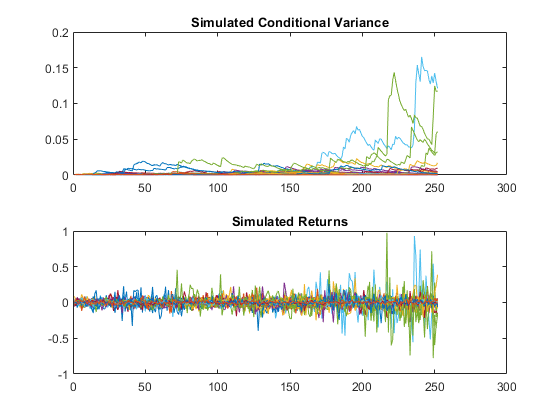

%画出10个路径上的模拟值
figure
subplot(2,1,1)
plot(V(:,1:100))
title('Simulated Conditional Variance')
subplot(2,1,2)
plot(Y(:,1:100))
title('Simulated Returns')

%计算预测波动率和历史波动率
tradingDays = 252;
LogReturns = rmmissing(LogReturns);
Fvol = mean(std(Y))*sqrt(tradingDays);
Hvol1Y = std(LogReturns)*sqrt(tradingDays);
disp(['Forecasted 1-year volatility = ' num2str(Fvol*100,4) '%'])

Forecasted 1-year volatility = 44.5%


disp(['Historical 1-year volatility = ' num2str(Hvol1Y*100,4) '%'])

Historical 1-year volatility = 45.65%
